## EE4530 Applied Convex Optimization mini-Project - SVM

## Clear all

clear all;
clc;
close all;

## 0.Data Load

load("linear_svm.mat");

Take a look to the data

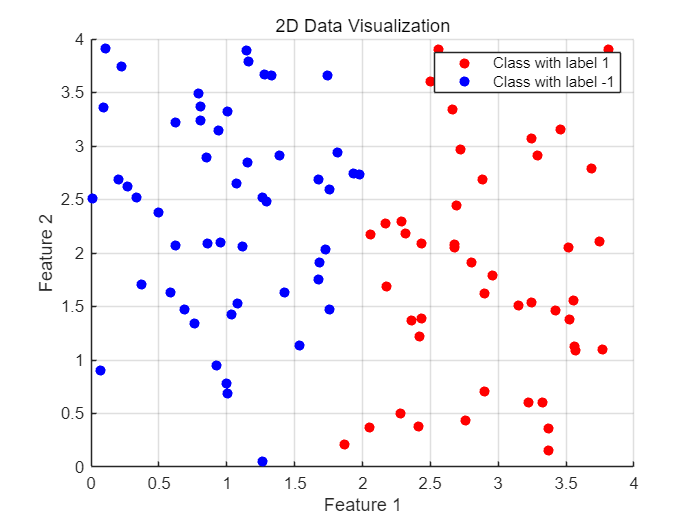

% plot the data
figure;

% plot data with label=1
scatter(X_train(labels_train == 1, 1), X_train(labels_train == 1, 2), 'ro', 'filled');
hold on;

% plot data with label=-1
scatter(X_train(labels_train == -1, 1), X_train(labels_train == -1, 2), 'bo', 'filled');

title('2D Data Visualization');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
% axis padded;
hold off;

## 1.Task 1

硬约束: svm最优化目标为最大化决策边界, 转化为下面的公式


$$\min_{\vec{w}} f(\vec{w})=\frac{||\vec{w}||^2}{2} \\
\text{s.t.}  \ g_i(\vec{w}, b) = y_i \cdot(\vec{w}\cdot \vec{x_i} + b) \geq 1

$$


[N_train, n] = size(X_train);
[N_test, n] = size(X_test);

tic;        % 运算时长
% Convex计算
cvx_begin
    variables w(n) b;
    % 目标
    minimize(0.5 * w'*w);

    % 约束条件
    subject to
        for i = 1:N_train
            labels_train(i) * (X_train(i, :) * w + b) >= 1;
        end
cvx_end

 
Calling SDPT3 4.0: 104 variables, 4 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  4
 dim. of socp   var  =  4,   num. of socp blk  =  1
 dim. of linear var  = 100
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.7e+02|2.4e+01|5.0e+04|-2.000000e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.410|0.416|5.7e+02|1.4e+01|4.0e+04|-1.397413e+03 -7.987107e+01| 0:0:00| chol  1  1 
 2|0.300|0.326|4.0e+02|9.3e+00|3.5e+04|-9.280953e+02 -2.648473e+02| 0:0:00| chol  1  1 
 3|0.202|0.255|3.2e+02|7.0e+00|3.3e+


time = toc;
disp('Optimal w: ');

Optimal w: 


disp(w);

   11.2556
   -1.9739



disp('Optimal b: ');

Optimal b: 


disp(b);

  -17.8885



disp('Running time: ');

Running time: 


disp(time);

    1.2039




y_pre = svm_predict(w, b, X_test);
accuracy = svm_report(labels_test, y_pre);
disp("Test Acc: ");

Test Acc: 


disp(accuracy);

    0.9767



## 2. Task 2

% 超参数
lambda = 0.01;
learning_rate = 0.01;
num_iters = 1000;

% data preprocessing
X_train_normalized = normalize(normalize(X_train), "range");
X_test_normalized = normalize(normalize(X_test), "range");

% 训练 SVM
tic;
[w, b] = svm_gd(X_train_normalized, labels_train, lambda, learning_rate, num_iters);
time = toc;

% 显示结果
disp('权重向量 w:');

权重向量 w:


disp(w);

    1.9229
   -0.7670



disp('偏置 b:');

偏置 b:


disp(b);

   -0.5400




disp(time);

    0.0053



y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
disp("Test Acc: ");

Test Acc: 


disp(accuracy);

    0.9444

